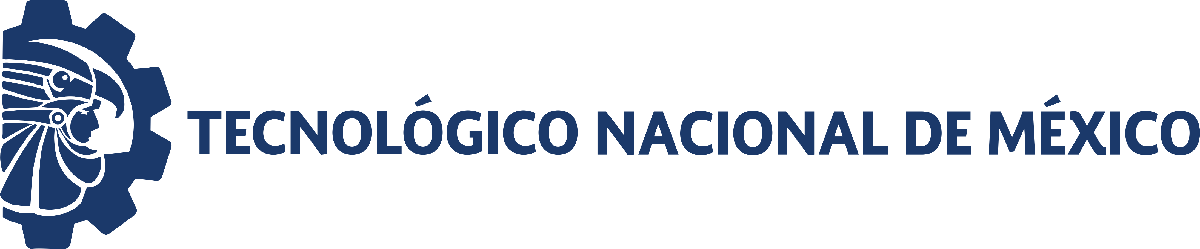                                 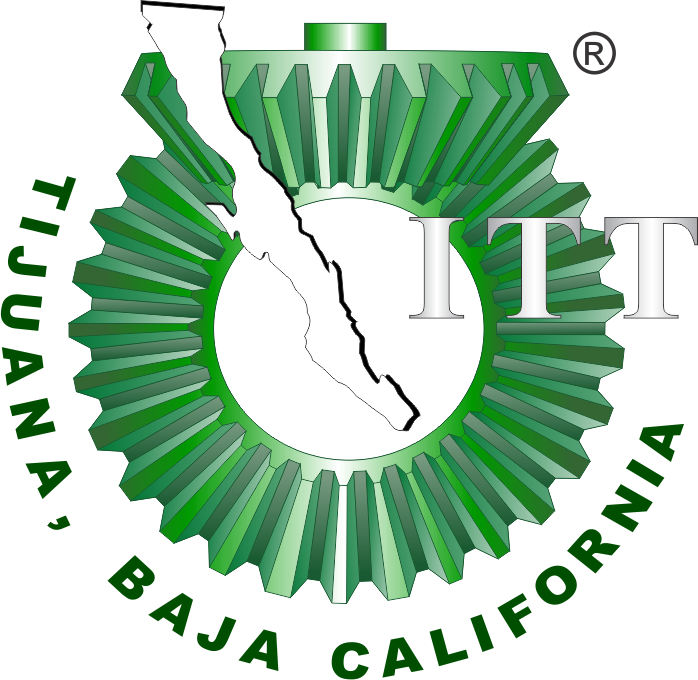

# Práctica: Sistema Musculoesqueletico 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

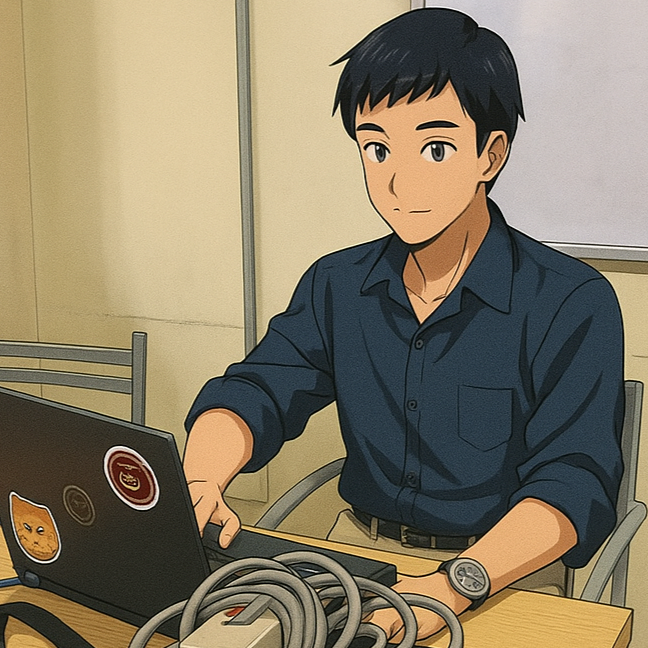

Nombre del alumno: Porfirio Emmanuel Ramirez Barajas

Número de control: 22211763

Correo institucional: L22211763**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';

## Respuesta en lazo abierto

x = sim(file, parameters);

Found algebraic loop containing: 
Sistema/PID Controller/D Gain/Internal Parameters/Derivative Gain
Sistema/PID Controller/Filter/Cont. Filter/SumD (algebraic variable)
Sistema/PID Controller/N Gain/Internal Parameters/Filter Coefficient
Sistema/PID Controller/Sum/Sum_PID/Sum
Sistema/PID Controller/Ideal P Gain/Internal Parameters/Proportional Gain


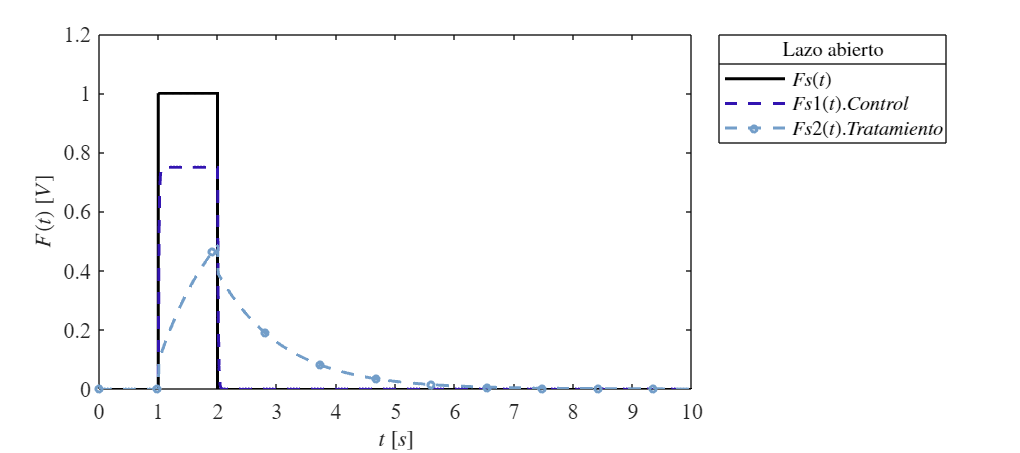

plotSignals(x.t,x.Fs,x.Fs1,x.Fs2)

## Respuesta en lazo cerrado

x = sim(file,parameters);

Found algebraic loop containing: 
Sistema/PID Controller/D Gain/Internal Parameters/Derivative Gain
Sistema/PID Controller/Filter/Cont. Filter/SumD (algebraic variable)
Sistema/PID Controller/N Gain/Internal Parameters/Filter Coefficient
Sistema/PID Controller/Sum/Sum_PID/Sum
Sistema/PID Controller/Ideal P Gain/Internal Parameters/Proportional Gain


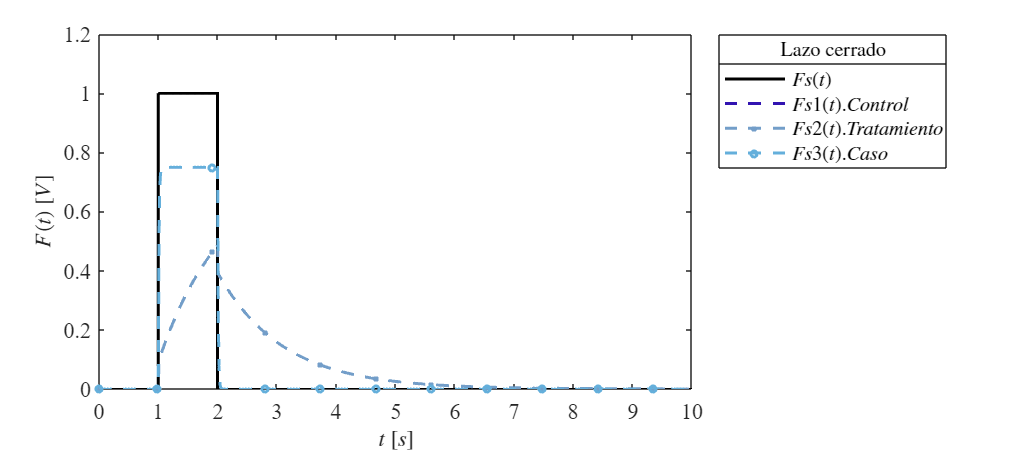

plotsignals(x.t,x.Fs,x.Fs1, x.Fs2, x.Fs3)

## Función: Respuesta en Lazo Abierto

function plotSignals(t,Fs,Fs1,Fs2)
Signal = 'Lazo Abierto';
set(figure(),'Color','w')
set(gcf,'units','centimeters','position',[1,1,18,8])
set(gca,'FontName','Times New Roman', 'FontSize', 11)
hold on; grid off; box on;
mycolors = [0,0,0;
 50,20,177;
 115,158,201;
 100,175,219;
 10,51,160;
 30,80,90]/255;
colororder(mycolors)

 p= plot(t,Fs,'-',t,Fs1,'--',t,Fs2,'--o', ...
 'LineWidth',1.5,'MarkerSize',3,'MarkerIndices',1:1000:length(t));
 set(p(3),'LineWidth',1.5);
 L = legend('$Fs(t)$','$Fs1(t). Control$','$Fs2(t). Tratamiento$');

set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
 title(L,['Lazo abierto'],'FontSize',10)
 xlabel('$t$ $[s]$', 'Interpreter', 'latex','FontSize', 11)
 ylabel('$F(t)$ $[V]$', 'Interpreter', 'latex','FontSize', 11)
 xlim([0,10]);xticks(0:1:10);
 ylim([0,1.2]);
 exportgraphics(gcf,[Signal,'.pdf'],'ContentType', 'vector');
 exportgraphics(gcf,[Signal,'.png'],'ContentType', 'vector');
end




## Función: Respuesta en Lazo cerrado

function plotsignals(t,Fs,Fs1, Fs2, Fs3)
Signal = 'LazoCerrado';
set(figure(),'Color','w')
set(gcf,'units','centimeters','position',[1,1,18,8])
set(gca,'FontName','Times New Roman', 'FontSize', 11)
hold on; grid off; box on;
mycolors = [0,0,0;
 50,20,177;
 115,158,201;
 100,175,219;
 10,51,160;
 30,80,90]/255;
colororder(mycolors)

 p= plot(t,Fs,'-',t,Fs1,'--',t,Fs2,'--x',t,Fs3,'--o', ...
 'LineWidth',1.5,'MarkerSize',3,'MarkerIndices',1:1000:length(t));
 set(p(1),'LineWidth',1.5);
 L = legend('$Fs(t)$','$Fs1(t). Control$','$Fs2(t). Tratamiento$','$Fs3(t). Caso$');

set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','On');
 set(p(2),'LineWidth', 1.5);
 title(L,['Lazo cerrado'],'FontSize',10)
 xlabel('$t$ $[s]$', 'Interpreter', 'latex','FontSize', 11)
 ylabel('$F(t)$ $[V]$', 'Interpreter', 'latex','FontSize', 11)
 xlim([0,10]);xticks(0:1:10);
 ylim([0,1.2]);

 exportgraphics(gcf,[Signal,'.pdf'],'ContentType', 'vector');
 exportgraphics(gcf,[Signal,'.png'],'ContentType', 'vector');
end